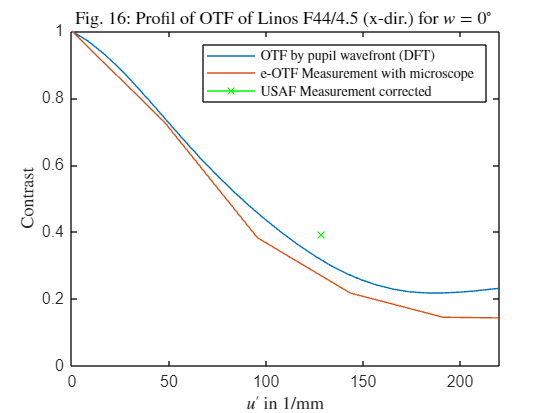

%% Comparison of Simulation with Measurement
% The following lens is to be investigated: microprojection lens Linos F44/4,5, 
% order #: G038846000
% 
% Specification according to  data sheet:
% * Effective focal length f'=44mm
% * F-Number (f/#) k=4,5
% * Field angle (2w) 44°
% * m=1:14
close all, clear all
%% Optical data of the lens
addpath(genpath('C:\Users\locsupp\Downloads\RTTB_v10\documented')) % Add folder and all subfolders of RTTB to search path


linos_f44=load_linos_f44();
[efl_linos_f44, bfl_linos_f44, ffl_linos_f44]=par_data_basic(linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n);
%% Spot-Diagramm
w=0; % field angle
N_trace_sq=51; % square root of number of rays
warning off, [r_pos,r_dir,OPL]=spot_diag_inf(linos_f44, w, N_trace_sq); warning on 
[r_dz_pos, OPL_dz, d_z]=spot_diag_min_rms(r_pos,r_dir,OPL,linos_f44.n(linos_f44.n_surf,1));
% set image plane to the desired value:
linos_f44.d(end)=bfl_linos_f44+d_z;
z_Pq=image_distance(linos_f44.d_P-linos_f44.d(1),linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n)+sum(linos_f44.d(1:linos_f44.n_surf-1));
d_PqOq=sum(linos_f44.d(1:linos_f44.n_surf))-z_Pq;
%% OTF:
N=512;
[OTF, du_q, l_Pq]=rayspot2OTF(linos_f44,r_dz_pos,r_dir, OPL_dz, d_PqOq, N);
% Samplings from OTF
% sampling in spatial frequency domain
u_q=((0:N-1)-N/2)*du_q; v_q=u_q;
% sampling in image plane
dx_q=1/du_q/N; dy_q=dx_q;
x_q=((0:N-1)-N/2)*dx_q; y_q=x_q;
% sampling period in exit pupil
dy_Pq=d_PqOq*linos_f44.la(1)/(dy_q*N);

%% calculate profiles
dir='x'; % direction in the image plane ('x' or 'y')
if dir == 'x', dir_uv='u'; elseif dir=='y', dir_uv='v'; end
if dir == 'x'
    N_max=fix(2*l_Pq(1)/dy_Pq); %Index of limiting spatial frequency
    ind_profile=N/2+1:N/2+1+N_max;
    OTF_profile=abs(OTF(N/2+1,ind_profile));
    NA_q=l_Pq(1)/d_PqOq;
elseif dir == 'y'
    N_max=fix(2*l_Pq(2)/dy_Pq); %Index of limiting spatial frequency
    ind_profile=N/2+1:N/2+1+N_max;
    OTF_profile=abs(OTF(ind_profile,N/2+1));
    NA_q=l_Pq(2)/d_PqOq;
end

u_q_profile=u_q(ind_profile);

u_max=2*NA_q/linos_f44.la(1);
% Comparison with diffraction limited OTF
OTF_b=real(1/pi*(2*acos(abs(u_q_profile)/u_max)-sin(2*acos(abs(u_q_profile)/u_max)))); % ideal OTF (= FT{Airy})

%% E-SFR Measurement
% Set path to image file
p=strsplit(userpath,'\');
p=strjoin(p(1:end-1),'\');
p =[p '\VL\Optische Systeme\Matlab\'];
if 1 % with microscope
    filename='3 - ESFR_5°_microscope_w0_2group.bmp';
    m_measure=5.0; % magnification of microscope
    roi=[309 217 23 74];
else % without microscope
    filename='10 - ESFR_5°_w0_2group.bmp';
    m_measure=1.0; % magnification without microscope
    roi=[335 259 22 53];
end
a = double(imread([p filename])); 
a=double(a(roi(2):roi(2)+roi(4)-1,roi(1):roi(1)+roi(3)-1));

N_bin=4; % binning factor 
sigma=1.7; % sigma of Gaussian low pass filter
[esf_bin,x_esf_c, alpha ] = edge_image_2_binned_esf(a,N_bin,sigma);

h_pp=0.00465; % pixel pitch in mm
c_ff=1.0; % Fill factor (area)
h_pix=sqrt(c_ff)*h_pp;

[etf_0, u_0]=esf2etf(esf_bin,h_pp/N_bin,1/h_pp);
etf_optical_0=abs(etf_0./sinc(u_0*h_pix));

%% USAF Measurement (50% Contrast)
u_50_USAF=22.62; % measured structure (group 5 element 2) with 50% contrast
m=-44/250; % magnification from USAF to image plane of lens
u_q_50_USAF=u_50_USAF/abs(m);
% correct for rectangular structure by factor of Fourier series
C_50_corr=0.5/4*pi;

%% Plot comparison
figure(1), clf
plot(u_q_profile,OTF_profile, u_0*m_measure, etf_optical_0)
hold on
line(u_q_50_USAF, C_50_corr, 'Marker','x','Color','g')

title({['Fig. 16: Profil of OTF of Linos F44/4.5 (' dir '-dir.) for $w = $', num2str(w/pi*180), '$^\circ$ ']...
%    ,['']...
    },'Interpreter','Latex')
xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex')
ylabel('Contrast','Interpreter','Latex')
legend({'OTF by pupil wavefront (DFT)',...
    'e-OTF Measurement with microscope',...
    'USAF Measurement corrected'},...
    'Interpreter','Latex')
xlim([0 220])
ylim([0 1])


%% Local Functions

function linos_f44=load_linos_f44()
    % Number of surfaces (including sensor surface)
    linos_f44.n_surf=8;
    % Curvatures of lens surfaces:
    linos_f44.c=[1/14.1;  0;  1/-29.6; 1/13.0; 1/-91.1;  1/14.57;  1/-21; 0];
    % Distances from surface to surface:
    linos_f44.d=[10;  2.76;  1.94;  1.49;  1.9;  1.07;  2.9;  38.19];
    % Refraction indices at specified wavelengths:
    linos_f44.n=[1.0  1.0  1.0;  1.6127203  1.6199982  1.6095434;  1.0  1.0  1.0;  ...
        1.5955102  1.6062267  1.5910209;  1.0  1.0  1.0;  1.5294405  1.5365924   1.5263331;    ...
        1.6967325  1.7053140  1.6929600; 1.0  1.0  1.0;];
    %Glasses (Schott): SK4;  F8;  KZFN2;  LAK31;
    % Typ of surface (a=0: spherical surface):
    linos_f44.a=[0; 0; 0; 0; 0; 0; 0; 0;];
    % Heights of surfaces
    linos_f44.h=[5.5;  5.5;  5.0; 5.0;  5.5;  5.5;  5.5;  16.77];
    % Max. field angle
    linos_f44.w=22*pi/180;
    % Wavelength
    % linos_f44.la=[0.00058756 0.00048613 0.00065627]; % g b r  standard wavelength
    linos_f44.la=0.00053; % wavelength of lab experiment

    % Position of the stop
    d_stop=sum(linos_f44.d(1:4))+0.64; % data sheet: sum(linos_f44.d(1:4))
    h_stop=4.07; % data sheet: 4.04

    % Calculate entrance pupil from stop
    [linos_f44.d_P, linos_f44.l_P]=find_EP(linos_f44.n_surf, linos_f44.d, linos_f44.c, linos_f44.n, d_stop, h_stop);
end

function [r_dz_pos, OPL_dz, d_z]=spot_diag_min_rms(r_pos,r_dir,OPL,n_q)
    pos_rms=plane_min_rms(r_pos, r_dir);
    d_z=pos_rms(3); % defocus
    r_dz_pos=r_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*d_z; % spots at defocus
    OPL_dz=OPL+n_q*d_z./r_dir(3,:);
end

function  [OTF, du_q, l_Pq]=rayspot2OTF(opt_sys,r_pos,r_dir, OPL, d_PqOq,N, h_pp, y_max)
    r_Pq_pos=r_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*(-d_PqOq);
    OPL_Pq=OPL+opt_sys.n(opt_sys.n_surf,1)*(-d_PqOq)./r_dir(3,:);
    % subtract spherical wave
    OPD_Pq=OPL_Pq+opt_sys.n(opt_sys.n_surf,1)*sqrt(r_Pq_pos(1,:).^2+(r_Pq_pos(2,:)-mean(r_pos(2,:))).^2+d_PqOq^2);
    % subtract constant path length
    [min_pos,ind_min_pos]=min(sum(r_Pq_pos(1:2,:).^2));
    OPD_Pq=OPD_Pq-OPD_Pq(ind_min_pos);
    %% Interpolate Data on a Grid
    if mod(N,2) ~= 0, warning('N not even! indexing is not correct.'), end
    if nargin < 8
        y_max=10*max(max(abs(r_Pq_pos(1,:))),max(abs(r_Pq_pos(2,:)))); % +/- height of the amplitude distribution
    end
    % choose y_max in order that h_pp is an multiple integer of dy_q
    % dy_q=d_PqOq*opt_sys.la/(2*y_max);
    if nargin > 6 && ~isempty(h_pp)
        y_max=round(h_pp/(d_PqOq*opt_sys.la(1)/(2*y_max)))*d_PqOq*opt_sys.la(1)/2/h_pp;
    end
    dy_Pq=2*y_max/N;
    y_Pq=((0:N-1)-N/2)*dy_Pq; %y-Koordinaten der AP
    x_Pq=((0:N-1)-N/2)*dy_Pq; %x-Koordinaten der AP
    [X_Pq,Y_Pq]=meshgrid(x_Pq,y_Pq);
    %% Interpolate the OPD data on the regular grid
    OPD_Pq_I=NaN(N);
    % grid indices of the exit pupil
    ind_Pq_gd_x=find((x_Pq >= min(r_Pq_pos(1,:))) & (x_Pq <= max(r_Pq_pos(1,:))));
    ind_Pq_gd_y=find((y_Pq >= min(r_Pq_pos(2,:))) & (y_Pq <= max(r_Pq_pos(2,:))));
    warning off
    OPD_Pq_I(ind_Pq_gd_y,ind_Pq_gd_x)=griddata(r_Pq_pos(1,:),r_Pq_pos(2,:),...
        OPD_Pq,X_Pq(ind_Pq_gd_y,ind_Pq_gd_x),Y_Pq(ind_Pq_gd_y,ind_Pq_gd_x), 'cubic');
    warning on
    %% Wavefront from OPD
    dW_Pq= OPD_Pq_I/opt_sys.la(1);
    %% Calculate PSF and OTF from the wavefront
    % Amplitude distribution in the exit pupil from wavefront
    A_Pq=zeros(N);
    ind_p_q=find(~isnan(dW_Pq));
    A_Pq(ind_p_q) = exp(j*2*pi*dW_Pq(ind_p_q));
    % Amplitude distribution in the image plane by DFT and PSF
    A_q=fftshift(fft2(ifftshift(A_Pq)));
    A_q=A_q/sum(sum(abs(A_Pq))); % normalization to constant power

    PSF=abs(A_q).^2; % irradiance
    dy_q=d_PqOq*opt_sys.la/(dy_Pq*N);
    % OTF from PSF by DFT
    OTF = fftshift(fft2(ifftshift(PSF))); % calculate OTF by DFT oft PSF
    OTF=OTF/sum(sum(abs(PSF))); % normalization
    du_q=1/dy_q/N;
    l_Pq(1)=(max(r_Pq_pos(1,:))-min(r_Pq_pos(1,:)))/2; %Index of limiting spatial frequency
    l_Pq(2)=(max(r_Pq_pos(2,:))-min(r_Pq_pos(2,:)))/2;
end

function [esf_bin,x_esf_c, alpha] = edge_image_2_binned_esf(a, N_bin, sigma)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
    if nargin < 2, N_bin=4; end
    if nargin < 3, sigma=1.7; end % sigma of Gaussian

    [N_lin N_pix] = size(a);

    N_Gauss=2*ceil(2*sigma)+1; % length of the kernel (odd)
    Gauss=fspecial('gaussian',[1 N_Gauss],sigma); % Gaussian kernel
    pix_pos=(1:N_pix); % pixel positions
    for i=1:N_lin;
        pix_val_canny=conv(a(i,:),Gauss,'valid'); % filtering the profile
        pix_val_canny_der=diff(pix_val_canny); % derivative of profile
        [max_pix,ind_max]=max(abs(pix_val_canny_der)); % extremum of profile
        if ind_max==1 | ind_max==length(pix_val_canny_der), error('max at edge: ROI too small'), end % check if extremum is at the edge of the profile
        pix_der2_sel=diff(pix_val_canny_der([ind_max-1 ind_max ind_max+1])); % calculate 2nd derivative
        if prod(pix_der2_sel) >0, error('Not a central maximum for CANNY'); end
        loc(i)=pix_pos(ind_max-1+(N_Gauss-1)/2)+(1-pix_der2_sel(1)/diff(pix_der2_sel)); % calculate zero crossing
    end
    %% Fit a line to the edge locations and determine angle of that line
    fitme = zeros(1, 3);
    fitme(1:2) = polyfit(0:N_lin-1, loc,1);

    alpha=atan(abs(fitme(1)));
    %disp(['Slope angle of edge: ' num2str(180*alpha/pi) '°'])
    %% Project the profiles along the direction of the edge (i.e. the fitted line)

    pos_project_lin=repmat((0:N_lin-1)'*sin(atan(-fitme(1))),1,N_pix); % positions of the projected profiles
    offset_project=-((1:N_pix) - fitme(2))*cos(atan(fitme(1))); % offset of the projected profiles

    x=pos_project_lin-repmat(offset_project,N_lin,1); % x-coorinates of each row after projection
    %% Binning
    dx_bin=1/N_bin;
    N_esf_bin=floor(N_pix*cos(atan(fitme(1)))/dx_bin); % number of bins
    x_edg=-N_esf_bin*dx_bin/2:dx_bin:N_esf_bin*dx_bin/2; % edges of bins

    [bincounts,ind]= histc(x(:),x_edg);
    esf_bin=zeros(1,N_esf_bin);
    for i=1:N_esf_bin
        if bincounts(i)
            esf_bin(i)=sum(a(ind==i))/bincounts(i);
        end
    end
    x_esf_c=(x_edg(1:N_esf_bin)+x_edg(2:N_esf_bin+1))/2;
end

function [etf_0,u_0] = esf2etf(esf, dx, u_max, N_zp, flag_hamming)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
    if nargin < 3, u_max=1/dx; end
    if nargin < 5, flag_hamming=false; end
    
    lsf=diff(esf);
    N_lsf=length(lsf);
    
    if flag_hamming
        % to do: shift lsf to center
        win=NaN(size(lsf));
        win(:)=hamming(N_lsf,'periodic');
        lsf = lsf.*win;
    end
    
    if nargin>3 && ~isempty(N_zp) && N_zp>0
        lsf=[zeros(1,N_zp) lsf zeros(1,N_zp)];
        N_lsf=N_lsf+2*N_zp;
    end
    du=1/dx/N_lsf; % spatial frequency sampling
    
    etf = fftshift(fft(ifftshift(lsf)));
    etf = etf/sum(lsf);
    
    % Correct SFR for response of the diff -FIR filter (length of 2 pixels)
    if mod(N_lsf,2) == 0
        corr=1./sinc((-(N_lsf/2):1:(N_lsf/2-1))/N_lsf);
    else
        corr=1./sinc((-(N_lsf-1)/2:1:(N_lsf-1)/2)/N_lsf);
    end
    corr(abs(corr)>10)=10*sign(corr(abs(corr)>10)); %limit corr to max. of 10
    
    etf=etf(:)'.*corr(:)';
    
    if mod(N_lsf,2) == 0
        u=(-(N_lsf/2):1:(N_lsf/2-1))*du;
        u_pos=u(N_lsf/2+1:end);
        etf_pos=abs(etf(N_lsf/2+1:end));
    else
        u=(-(N_lsf-1)/2:1:(N_lsf-1)/2)*du;
        u_pos=u((N_lsf-1)/2+1:end);
        etf_pos=abs(etf((N_lsf-1)/2+1:end));
    end
    ind_u_max=find(u_pos/u_max > 1,1,'first');
    if isempty(ind_u_max), ind_u_max=length(u_pos); end
    etf_0=etf_pos(1:ind_u_max);
    u_0=u_pos(1:ind_u_max);
end